# **PESTools - Example 010-012 - ARPES Eb(kx) Data Processing**

## PCC

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

% Code initialisation
close all; clear all;
pp          = plot_props();
data_path   = 'G:\My Drive\GitHub\ADRESSTools\ADRESSTools_Ajax\PESTools_PCC\Examples\Example_Data\';
save_path   = 'G:\My Drive\GitHub\ADRESSTools\ADRESSTools_Ajax\PESTools_PCC\Examples\Example_Data\';

# **ARPES Eb(kx) Data Processing**

**(A) Loading in the ARPES data files**

% Loading in the data files
file_names      = {...
    '010_ARPES_HSCUT.h5',...
    };
VB_dat = cell(1,length(file_names));
for i = 1:length(file_names); VB_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ARPES data...


- Data slice formation
- Re-mapping


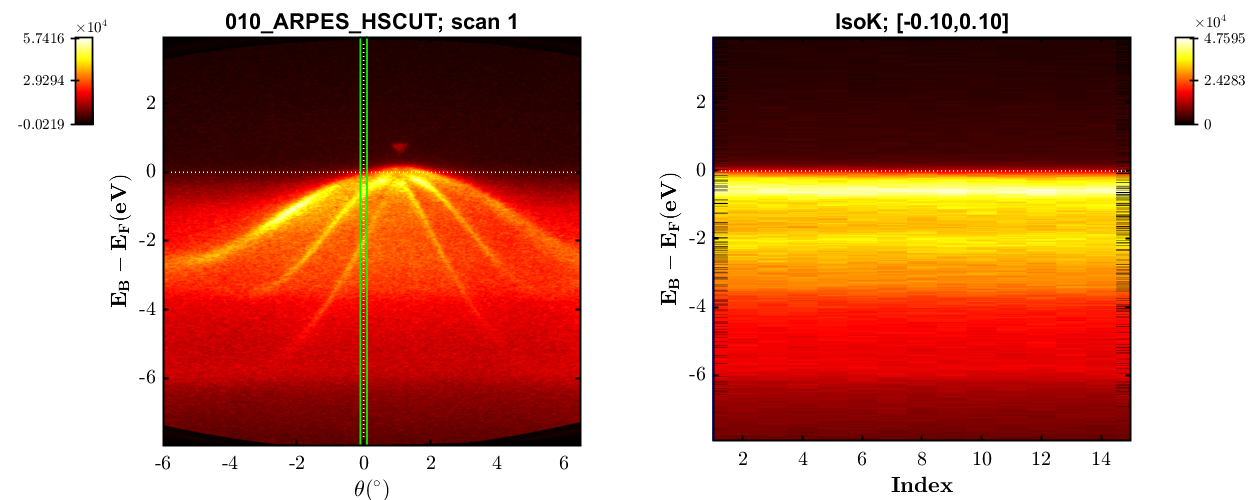

view_data(VB_dat{1});

% Cross-correlating the data files
for i = 1:length(VB_dat); VB_dat{i} = xcorr_scans(VB_dat{i}); end

- Correlating scans
Scan = 2: Offset = 0.01728
Scan = 3: Offset = 0.01728
Scan = 4: Offset = 0.01728
Scan = 5: Offset = 0.02592
Scan = 6: Offset = 0.02592
Scan = 7: Offset = 0.02592
Scan = 8: Offset = 0.02592
Scan = 9: Offset = 0.02592
Scan = 10: Offset = 0.02592
Scan = 11: Offset = 0.03456
Scan = 12: Offset = 0.03456
Scan = 13: Offset = 0.03456
Scan = 14: Offset = 0.03456
Scan = 15: Offset = 0.03456


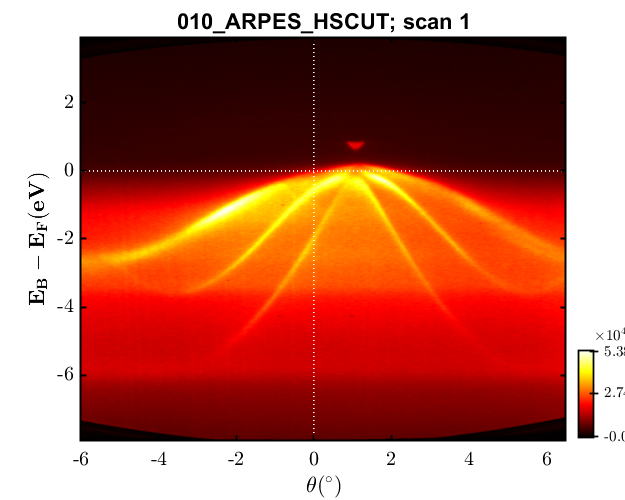

view_data(VB_dat{1});

**(B) Loading in the Fermi-Edge reference files**

% Loading in the data files
file_names_ef      = {...
    '010_ARPES_HSCUT_EF.h5',...
    };
VB_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); VB_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ARPES data...


- Data slice formation
- Re-mapping


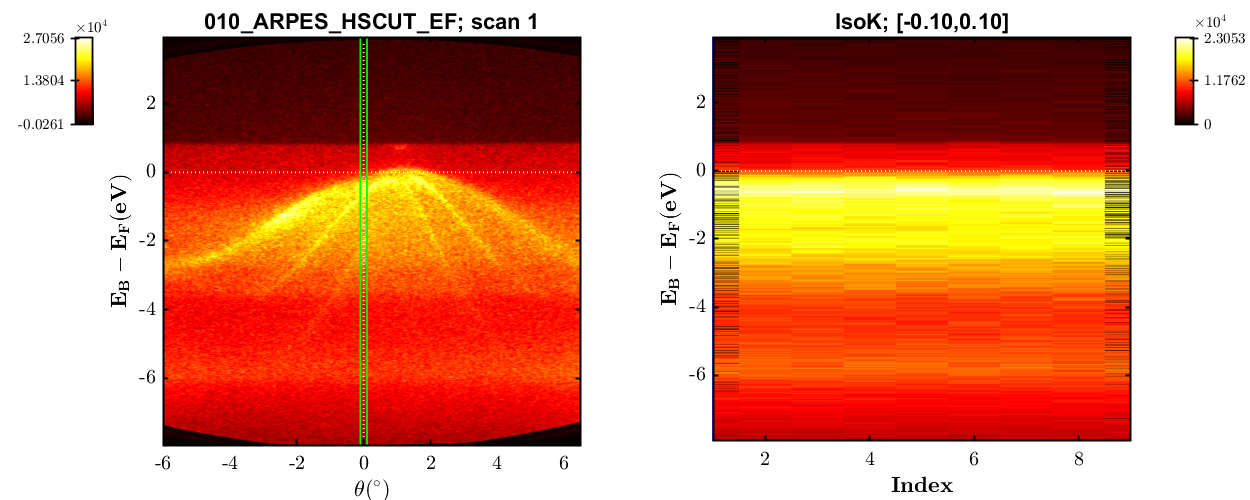

view_data(VB_ref{1});

% Cross-correlating the reference files to get a good estimate on EF
for i = 1:length(VB_ref); VB_ref{i} = xcorr_scans(VB_ref{i}); end

- Correlating scans
Scan = 2: Offset = 0
Scan = 3: Offset = 0
Scan = 4: Offset = 0
Scan = 5: Offset = 0
Scan = 6: Offset = 0
Scan = 7: Offset = 0
Scan = 8: Offset = 0
Scan = 9: Offset = 0


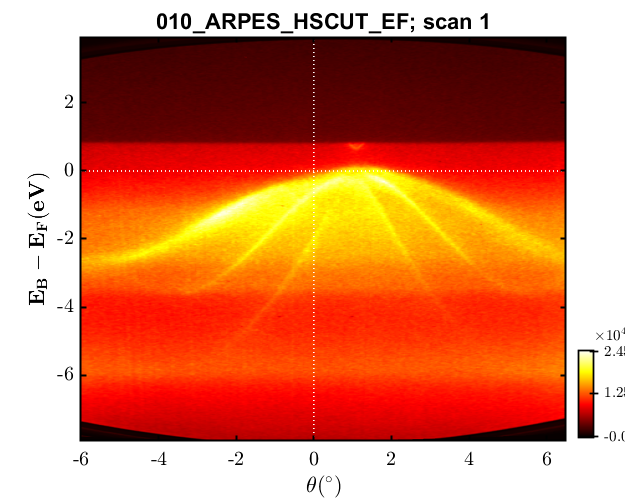

view_data(VB_ref{1});

**(C) Binding energy alignment to the reference data**

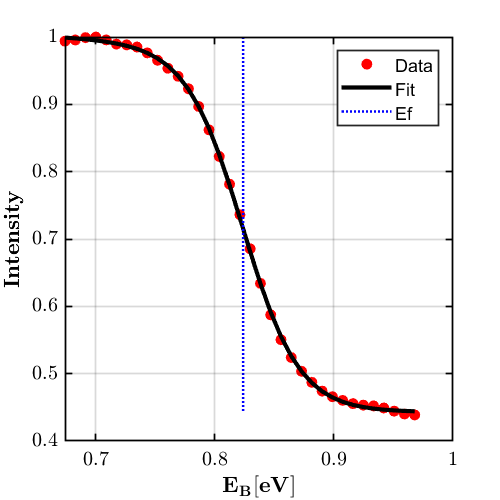

alignType   = "fit2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.82;             % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.15;             % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat}; 
for i = 1:length(VB_dat)
    VB_dat{i}  = align_energy(VB_dat{i}, align_args, VB_ref{1}, 1); 
end

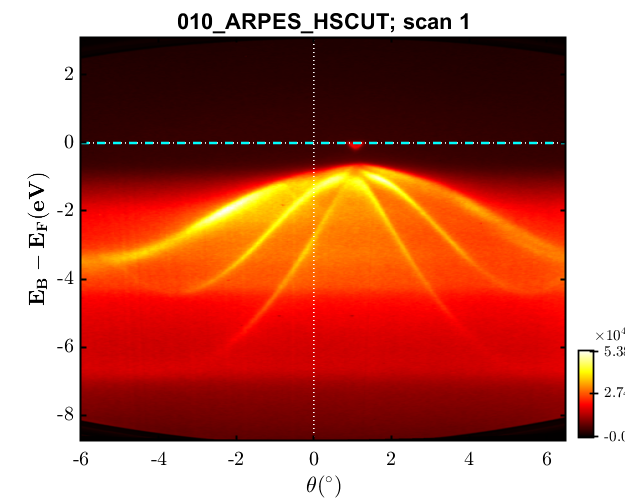

view_data(VB_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Background subtraction and intensity normalisation**

bgrdType    = "angle/kx-int (fixed edc) (per channel)";   % either "angle/kx-int (fixed edc)", "angle/kx-int (fixed edc) (per channel)", "angle/kx-int (fixed mean)", "angle/kx-int (moving mean)", "none"
bgrdWin     = [-5, 5];                  % EDC angle range to integrate over to extract ISubtr
bgrdScale   = 0.50;                         % scale coefficient to subtract (Data - intScale * ISubtr)
bgrdSmooth  = 100;                          % single, constant value that determine presmoothing of data to extract background. 
normType    = "mean (each scan)";           % "max (all scans)", "max (each scan)", "mean (each scan)", "none"
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
for i = 1:length(VB_dat)
    VB_dat{i} = bgrd_subtr_data(VB_dat{i}, bgrd_args); 
end

- Data cut formation


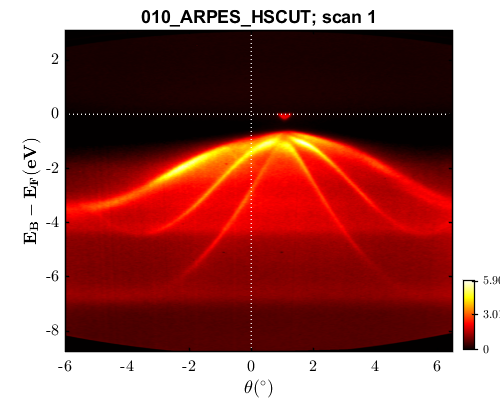

view_data(VB_dat{1});

**(E) Wave-vector conversions**

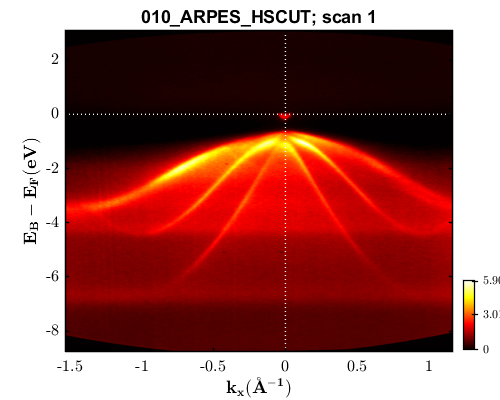

eB_ref      = 0;            % single, constant value of the binding energy at the refernece point.
kx_ref      = 0;            % single, constant value of the wave-vector value at the reference point.
thtA_ref    = 1.10;         % single, constant value of the tht angle value at the reference point.
v000        = 12.57;        % single, constant value of the inner potential. Tune to make sure spacing of Gamma points is correct. Default is 12.57.
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000}; 
for i = 1:length(VB_dat)
    VB_dat{i} = convert_to_k(VB_dat{i}, kconv_args);
    % -- custom shift to centralise kx
    VB_dat{i}.kx = VB_dat{i}.kx;
end
view_data(VB_dat{1});

**(F) Cropping the ARPES data**

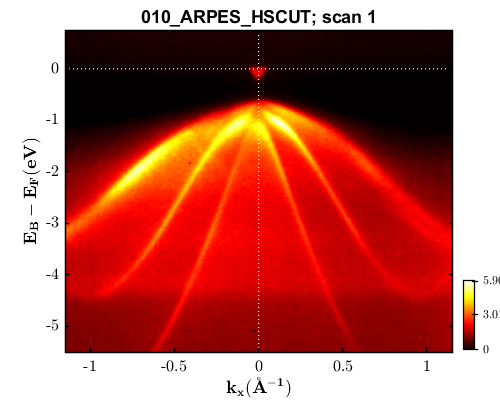

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
       raw_data: [1376×391 double]
        raw_tht: [1×391 double]
         raw_eb: [1376×1 double]
            deb: 0.0450
             hv: 586
            dhv: 0.0750
           tltM: 2.8006
           thtM: 0
           Temp: 81.9000
    eb_ref_file: '010_ARPES_HSCUT_EF'
      eb_shifts: {[0.8287]}
             eb: [725×335 double]
            tht: [725×335 double]
           data: [725×335 double]
      surfNormX: 0.1924
             kx: [725×335 double]
             ky: 0.6060
             kz: 12.5700


xLims       = [-1.15, 1.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-5.5, 0.75];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(VB_dat) 
    VB_dat{i} = data_crop3D(VB_dat{i}, xLims, yLims, zLims);
    view_data(VB_dat{i}); VB_dat{i}
end

# **APPENDIX : A LIST OF USEFUL FUNCTIONS**

## Appendix I - Extracting *iso-cut* profiles

- Data cut formation


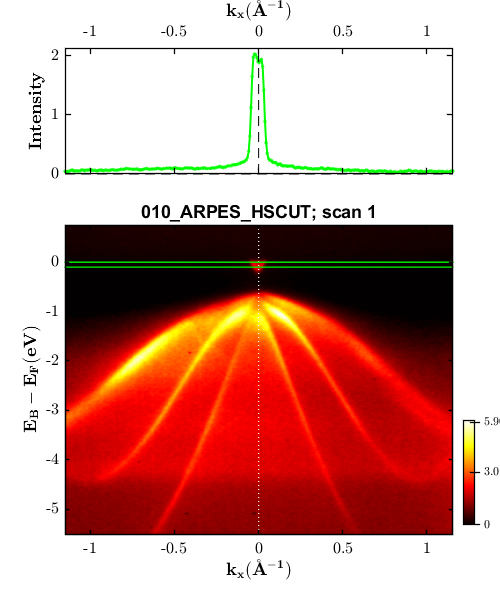

cutStr_01 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [-0.1000 0]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: -0.0500
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [1×335 double]
           DCut: [1×335 double]


nFrame          = 1;                    % Scan number to be cut
% -- EXTRACT MDC CUT
cutType         = "MDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.1, 0.0];          % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_01, ~]  = extract_isoCut(VB_dat{1}, isocut_args); cutStr_01

- Data cut formation


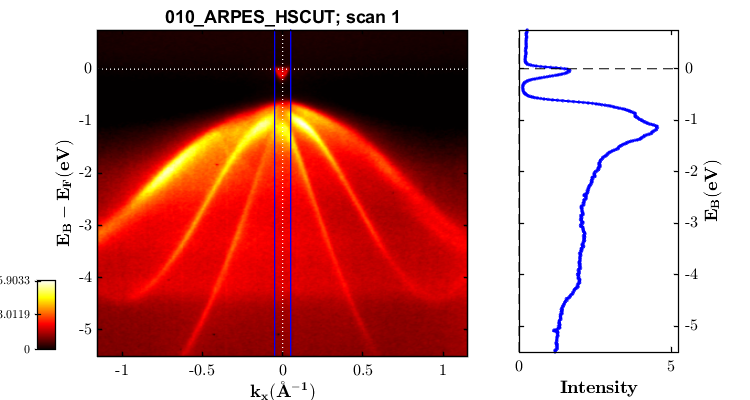

cutStr_02 = struct with fields:
    isocut_args: {[1]  ["EDC"]  [-0.0500 0.0500]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "EDC"
         IsoVal: 0
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [725×1 double]
           DCut: [725×1 double]


% -- EXTRACT EDC CUT
cutType         = "EDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.05, 0.05];        % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_02, ~]   = extract_isoCut(VB_dat{1}, isocut_args); cutStr_02

- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation


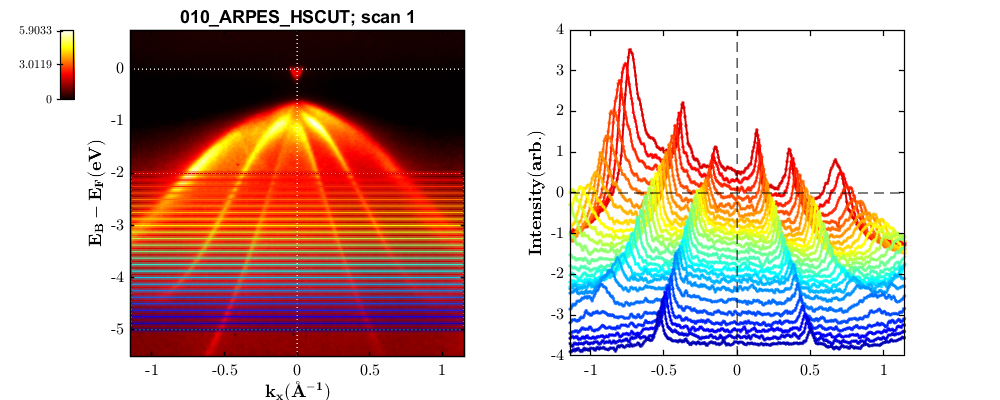

cutStr_03 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [0.0500]  [-1.7500 1.7500]  [-5 -2]  [25]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: [-5 -4.8750 -4.7500 -4.6250 -4.5000 -4.3750 -4.2500 -4.1250 -4 -3.8750 -3.7500 -3.6250 -3.5000 -3.3750 -3.2500 -3.1250 -3 -2.8750 -2.7500 -2.6250 -2.5000 -2.3750 -2.2500 -2.1250 -2]
         IsoWin: [-0.0500 0.0500]
         IsoNum: 25
           XCut: {1×25 cell}
           DCut: {1×25 cell}


% -- EXTRACT SERIES OF MDC CUTS
isocutType          = "MDC";            % Type of line profile to extract. "EDC" (vertical) or "MDC" (horizontal)
isocutWin           = 0.05;             % single, constant valueof the integration window.
isocutXLims         = [-1.75, 1.75];    % 1x2 vector which gives the x-axis limits of the train [minX, maxX]
isocutYLims         = [-5, -2];         % 1x2 vector which gives the y-axis limits of the train [minY, maxY]
isocutN             = 25;               % single, constant value that determines the total number of line profiles to extract
isocut_args         = {nFrame, isocutType, isocutWin, isocutXLims, isocutYLims, isocutN};
plot_result         = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[cutStr_03, ~]      = extract_isoCut_series(VB_dat{1}, isocut_args, plot_result); cutStr_03

## Appendix II - Fitting to the valence band leading edge at the Gamma Point

**(A) VB Leading Edge Fitting Method**

- Data cut formation


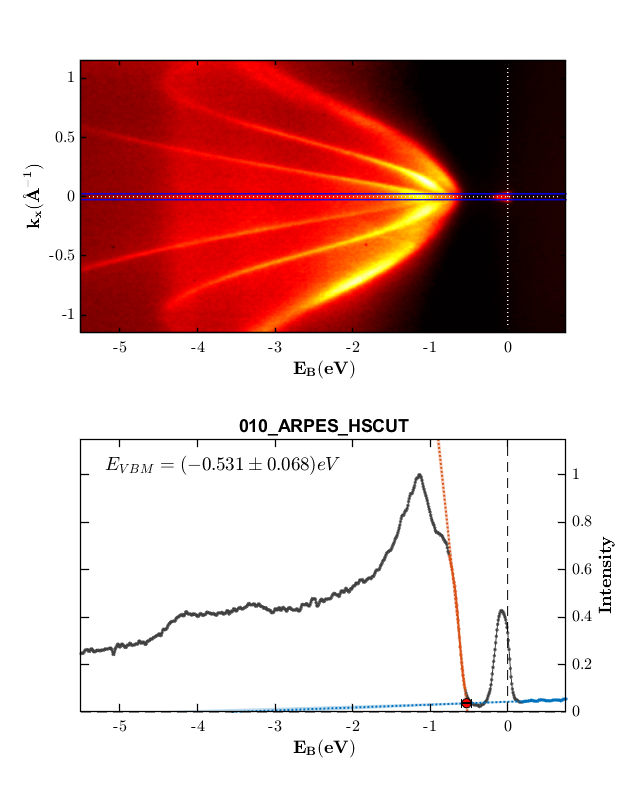

ans = struct with fields:
    vb_fit_args: {[-0.0250 0.0250]  [0.2000 0.7500]  [-0.7500 -0.5500]  []}
           XCut: [725×1 double]
           DCut: [725×1 double]
      XCut_back: [65×1 double]
      DCut_back: [65×1 double]
      XCut_edge: [24×1 double]
      DCut_edge: [24×1 double]
       fit_back: [1×1 cfit]
       fit_edge: [1×1 cfit]
             XX: [1000×1 double]
        DD_back: [1000×1 double]
        DD_edge: [1000×1 double]
          E_VBM: -0.5310
         dE_VBM: 0.0680


VB_LE_fit       = {};
kWin_edc        = 0.00 + [-0.025, 0.025];     % window of the EDC taken around the VBM position
eWin_back	    = [0.2, 0.75];            % window of the background region within the EDC cut
eWin_edge	    = [-0.75, -0.55];           % window of the VBM leading edge region within the EDC cut
dESmooth        = [];                       % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
vb_fit_args     = {kWin_edc, eWin_back, eWin_edge, dESmooth}; 
for i = 1:length(VB_dat)
    % -- Finding the VBM position from the leading edge fit
    VB_LE_fit{i}    = fit_vb_leading_edge(VB_dat{i}.kx, VB_dat{i}.eb, VB_dat{i}.data, vb_fit_args);
    title(VB_dat{i}.FileName, 'Interpreter','none');
    % -- Print the final fit
    VB_LE_fit{i}
end

% -- Finding the best estimate of the VBM and BOFF based on multiple data files
VBM = []; dVBM = [];
for i = 1:length(VB_dat)
    VBM(i)      = VB_LE_fit{i}.E_VBM;
    dVBM(i)     = VB_LE_fit{i}.dE_VBM;
end
VBM_mu      = mean(VBM)

VBM_mu = -0.5310

VBM_3sig    = 3*std(VBM)

VBM_3sig = 0